# Probing the Limits of Latent Reconstruction Methods

## 1. Ground Truth & Forward Model

**Why? **

              Building intuition for what the problem is. 

**Tasks:**

- Plot true latent trajectories , color‑coded by time. Compute their power spectra. 

- Plot example EEG trajectories  and compute their power spectra.

- Provide a short rationale (2‑3 sentences each):

- Which features of  are likely preserved in ?

- Which features (especially high-frequency) are likely lost or distorted?

clear;clc;

**Try different Simulation times and time constants (tau) to see how they change the PSD.**

% For the param.tau, since the model implementation of Ornstein Uhlenbeck
% uses the Euler_Maruyama the min tau should be: dt <= tau/50, for a dt =
% 0.01, tau = 0.01*50 = 0.5

% Parameters
T_vals = [100,  1000, 10000];       % Total simulation times (s)
tau_vals = [0.3, 0.5,  3,  50];               % OU time constants (s)
fs = 100;                                     % Sampling frequency (Hz)
param.dt = 1 / fs;                            % Time step
param.N_neur = 256;
param.N_F = 1;                                % Only 1 latent field for now (simplifies plotting)
param.fixJ_if = randn(param.N_neur, param.N_F) / sqrt(param.N_F);
param.eta_val = 3;
param.eps_val = 1 * param.eta_val;

% Welch settings
window = hamming(512);
noverlap = 256;
nfft = 4096;

% Color for each T
T_colors = lines(length(T_vals));

% Create figure
figure('Position', [50 50 1000 800])
tiledlayout(length(tau_vals), 1, 'TileSpacing', 'compact', 'Padding', 'compact')

% Loop over tau and T
for i_tau = 1:length(tau_vals)
    tau = tau_vals(i_tau);
    nexttile;    
    for i_T = 1:length(T_vals)
        T = T_vals(i_T);
        
        % Set model parameters
        param.T = T;
        param.tau_F = tau;  % Only 1 field, scalar tau
        
        % Run simulation
        [~, ~, h_f] = sampleMorrellModel(param);
        h = h_f(:, 1);  % Only one latent field

        % Compute Welch PSD
        [Pxx, f] = pwelch(h, window, noverlap, nfft, fs);
        
        % Plot
        loglog(f, Pxx, 'Color', T_colors(i_T,:), 'LineWidth', 1.5, ...
               'DisplayName', sprintf('T = %d s', T));
        hold on;
    end
    
    % Format subplot
    xlabel('Frequency (Hz)');
    ylabel('PSD (units^2/Hz)');
    title(sprintf('Welch PSD for \\tau = %.1f s', tau));
    legend('show');
    grid on;
    xlim([1, fs/2]);
end

sgtitle('PSD of Latent Variable for Varying Simulation Time (T) and OU Time Constant (\tau)');

- **Comparing simulation times, param.T (100, 1000, 10000), the Shorter simuilation time of 100 has a higher Welch PSD periodogram variation comapred to 1000 and 10000. **

- **Comparing the time constant, tau, of the Ornstein Uhlenbeck's process, the lower time constants of 0.3, 0.5 and 3 have less Welch PSD periodogram variation compared to 50. **

- Comparing tau of 0.3 and 0.5, I can't visually tell the difference in terms of variance or if the OU process is underperforming somehow. 

% Parameter setup and model invocation

param.N_neur = 256; % Number of "neurons" (binary units)
param.N_F = 4; % Number of latent fields hₘ(t)
param.tau_F = [0.5 1 3 10]; % Time constants (in seconds) for each OU field, min tau at 0.5 
param.T = 1000; % Total simulation time (in seconds), min duration at 1000 sec

param.fixJ_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F); % ordered_J_if; %
param.eta_val = 3;
param.eps_val = 1*param.eta_val; % 2.67 previous, "Inverse temperature" and silence bias
[s_i, param, h_f] = sampleMorrellModel(param);

TODO: use welch's method and study it! 

- What is the difference between the fourier and the welch's method. 

- calculate the 1/f slope for each tau with the EEG signal and see how different they are.

- Try different param.T and see how it changes the psd

- Try different param.tau and see how the PSD changes

#### Discrete Fourier Transform vs. Welch's Periodogram

% DFT Periodogram Method
N = length(h_f);
H_F = fft(h_f); % DFT
fs = 1/param.dt;
H_F_dft_psd = (1/(N*fs) * abs(H_F)) .^2; % normalizing to get the PSD
freq_dft = (0:N-1) * (fs/N);

% Welch's Periodogram
window = hamming(256);
overlap = 128; % 50 % overlap
nfft = length(h_f); % FFT length

[H_F_welch_psd, f_welch_psd] = pwelch(h_f, window,overlap,nfft,fs);

figure('Position',[50 50 800 600])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);

nexttile
hold on;
for f=1:param.N_F
    plot(h_f(:, f), 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
end
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')
xlim([0 1000]);
legend( 'Show');
hold off;

nexttile
for f=1:param.N_F
    loglog(freq_dft, H_F_dft_psd(:,f),'Color',h_f_colors(f,:),'DisplayName',['DFT(Z_{' num2str(f) '} (t))']);
    hold on;
end
xticks([1, 4, 8, 10, 13, 20, 30, 50]) 
xlabel('Freq. (Hz)'); ylabel('PSD (units^2/Hz)');
title('DFT Periodogram estimate');
legend('show');
xlim([1, fs/2]);
hold off;

nexttile
for f=1:param.N_F
    loglog(f_welch_psd, H_F_welch_psd(:,f),'Color',h_f_colors(f,:),'DisplayName',['Welch(Z_{' num2str(f) '} (t))']); % 
    hold on;
end
xticks([1, 4, 8, 10, 13, 20, 30, 50]) 
xlabel('Frequency bins')
ylabel('Power/Freq (dB/Hz)')
title('Welch Periodogram')
legend('show');
xlim([1, fs/2]);
hold off;

- The DFT periodogram has a higher variance for each latent variable PSD compared to the Welch's method. The averaging over many segments has smoothed out the noise. 

-  The DFT's frequency resolution is fs/N= 100/20000= 0.005, and by setting the length of fft to length (h_f) for Welch it is fs/L= 100/20000= 0.005, we have comparable frequency resolution.

- For stochastic signals and physiological signals Welch is a better method.

#### Removing EEG smoothing and seeing how it effects the R^2 reconstruction error

% Initializing parameters
target_bin_size = [0.02, 0.05]; % 50 ms
tau = [15, 25]; % Post-synaptic kernel, Alpha kernel's number of bins to the peak of the kernel
smooth_sigma = [2, 5]; % Std. Dev. of the Gaussian kernel in bins
group_size = 8; % grouping of neurons per channel

figure('Position',[50 50 800 800])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

for e=1:2
    [s_eeg_like, h_f_processed] = spike_to_eeg(s_i, h_f, param, target_bin_size(e), tau(e), group_size, smooth_sigma(e));
    s_eeg_like_T = s_eeg_like';

    % Marchenko–Pastur threshold
    eig_vals = eig(cov(s_eeg_like_T));
    [N, T] = size(s_eeg_like);
    Q = T / N;
    sigma2 = mean(eig_vals);           % crude estimate of noise variance
    lambda_max = sigma2 * (1 + sqrt(1/Q))^2;
    
    % Find number of components above the MP threshold
    num_sig_components = sum(eig_vals > lambda_max);
    fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

    [~, score, ~, ~, ~] = pca(s_eeg_like_T);
    
    % Normalize latent variables by their variance (per column)
    h_f_normalized = h_f_processed ./ std(h_f_processed, 0, 1);  % Time × N_F
    
    h_f_recon = zeros(size(h_f_processed));
    reconstruction_error_pca = zeros(num_sig_components, param.N_F,2); % The 3rd dimension: 1 for R^2, 2 for MSE
    
    for idx = 1:num_sig_components
        for f = 1:param.N_F
            % Train
            w = lsqlin(score(:,1:idx), h_f_normalized(:,f));
            h_f_recon(:,f) = score(:,1:idx) * w;
            % reconstruction_error_pca(idx, f) = mean((h_f(:,f) - h_f_recon_train).^2);
            numerator = sum((h_f_normalized(:,f) - h_f_recon(:,f)).^2);
            denominator = sum((h_f_normalized(:,f) - mean(h_f_normalized(:,f))).^2);
            reconstruction_error_pca(idx, f,1) = 1 - (numerator / denominator);
            reconstruction_error_pca(idx, f,2) = mean((h_f_normalized(:,f) - h_f_recon(:,f)).^2);
        end
    
    end
    
    nexttile;
    plot(s_eeg_like_T(:,1), 'LineStyle', '-', 'DisplayName', 'Ch 1 ' );
    
    nexttile
    for f = 1:param.N_F
        hold on;
        plot(reconstruction_error_pca(:,f,1), 'LineStyle', '-','Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['R^2 ' num2str(f)]);
        plot(reconstruction_error_pca(:,f,2), 'LineStyle', '--','Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['MSE ' num2str(f)]);
    end
    % Adding axis labels and title
    xlabel('Feature Index'); % X-axis label
    ylabel('R² Value');      % Y-axis label
    title('PCA R² Values for Different Features'); % Title
    grid("on");
    hold off;
    legend('show');

end

Marchenko–Pastur suggests keeping 5 PCs
Marchenko–Pastur suggests keeping 5 PCs


- MSE measures the average error magnitute, while the R^2 measures how much of the variance the model captures compared to just predicting the mean.

- The R^2 and MSE results are worse when we do smoothing of the EEG. For example for latent 4 the R^2 by PC 3 it achieves 0.9, while for smoothed EEG it is at about ~0.8. In addition, for latent 1, the MSE falls to ~0.65 by PC 5, while for smoothed EEG it platues at ~ 0.95.

target_bin_size = 0.02; % 50 ms
tau = 15; % Post-synaptic kernel, Alpha kernel's number of bins to the peak of the kernel
smooth_sigma = 2; % Std. Dev. of the Gaussian kernel in bins
group_size = 8; % grouping of neurons per channel

[s_eeg_like, h_f_processed] = spike_to_eeg(s_i, h_f, param, target_bin_size, tau, group_size, smooth_sigma);

% Normalize latent variables by their variance (per column)
h_f_normalized = h_f_processed ./ std(h_f_processed, 0, 1);  % Time × N_F

% — EEG‐like Welch PSD (after spike→EEG):
[eeg_welch_psd, f_eeg] = pwelch(s_eeg_like', window, overlap, nfft, fs);

fmin = 3;    % lower frequency bound in Hz
fmax = 50;   % upper frequency bound in Hz

% Find frequency indices:
idx_latent = find(f_welch_psd >= fmin & f_welch_psd <= fmax);
idx_eeg    = find(f_eeg    >= fmin & f_eeg    <= fmax);

nF = size(H_F_welch_psd, 2);
slopes_latent = zeros(nF,1);

for ff = 1:nF
    P = H_F_welch_psd(idx_latent, ff);        % PSD values
    x = log10(f_welch_psd(idx_latent));           % log‐freq
    y = log10(P);                             % log‐power
    
    % Fit y = m*x + b
    p = polyfit(x, y, 1);
    slopes_latent(ff) = p(1);                 % slope = exponent of 1/f
end

% If eeg_welch_psd is [nFreq × nCh]:
nCh = size(eeg_welch_psd, 2);
slopes_eeg = zeros(nCh,1);

for ch = 1:nCh
    P_eeg = eeg_welch_psd(idx_eeg, ch);
    x_eeg = log10(f_eeg(idx_eeg));
    y_eeg = log10(P_eeg);
    
    p_eeg = polyfit(x_eeg, y_eeg, 1);
    slopes_eeg(ch) = p_eeg(1);
end



figure('Position',[50 50 1000 800])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);

nexttile
hold on;
for f=1:param.N_F
    plot(h_f(:, f), 'Color', h_f_colors(f, :),'DisplayName', ['Z_' num2str(f)]);
end
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')
xlim([0 1000]);
legend( 'Show');
hold off;

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_processed(:, f), 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) processed ' num2str(f)]);
end
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables Z processed(t)')
xlim([0 1000]);
legend( 'Show');
hold off;

nexttile
h_legend = gobjects(2*nF,1);
labels   = cell(2*nF,1);

% define the two x‐points we'll use for every fit line:
xv = [fmin fmax];

for ff = 1:nF
    % 1) plot the raw PSD
    h_legend(2*ff-1) = loglog(...
        f_welch_psd, H_F_welch_psd(:,ff),...
        '.', 'Color', h_f_colors(ff,:), ...
        'DisplayName', sprintf('Welch Z_{%d}(t)', ff));
    hold on;
    % 2) overlay the fit line with its own handle
    %    here I let the intercept float so you can really see different slopes
    idx    = idx_latent;                           % frequency indices
    xdata  = log10(f_welch_psd(idx));
    ydata  = log10(H_F_welch_psd(idx,ff));
    p      = polyfit(xdata, ydata, 1);             %  p(1)=slope, p(2)=intercept
    yv     = 10.^( polyval(p, log10(xv)) );        % full line with intercept
    
    h_legend(2*ff) = loglog(...
        xv, yv, '-', ...
        'Color',     h_f_colors(ff,:), ...
        'LineWidth', 2, ...
        'DisplayName', sprintf('Fit Z_{%d}(t): slope = %.2f', ff, p(1)) );
end
xticks([1, 4, 8, 10, 13, 20, 30, 50]) 
xlabel('Frequency (Hz)')
ylabel('PSD (units^2/Hz)')
title('Welch PSD and 1/f Fits for each latent field')
legend(h_legend,'Location','best');
xlim([1, fs/2]);
hold off;

nexttile
% Plot EEG

% Compute EEG average PSD and log-log fit
mean_psd_eeg = mean(eeg_welch_psd, 2);  % [nFreq x 1]
logf_eeg = log10(f_eeg(idx_eeg));
logP_eeg = log10(mean_psd_eeg(idx_eeg));

p_eeg = polyfit(logf_eeg, logP_eeg, 1);  % [slope, intercept]
yv_eeg = 10.^polyval(p_eeg, log10(xv));  % correct use of both slope and intercept

% Plot
loglog(f_eeg, mean_psd_eeg, 'k.', 'DisplayName', 'EEG avg');
hold on;
loglog(xv, yv_eeg, 'k-', 'LineWidth', 2, 'DisplayName', sprintf('EEG fit: slope = %.2f', p_eeg(1)));
xticks([1, 4, 8, 10, 13, 20, 30, 50]) 
xlabel('Frequency (Hz)');
ylabel('PSD (units^2/Hz)');
title('Log–Log PSD and 1/f Fits');
legend('Location', 'best');
xlim([1, fs/2]);
hold off;


fprintf('Latent slope: %.3f ± %.3f\n', mean(slopes_latent), std(slopes_latent));

Latent slope: -1.671 ± 0.011


fprintf('EEG   slope: %.3f ± %.3f\n', mean(slopes_eeg),   std(slopes_eeg));

EEG   slope: -2.008 ± 0.074



[p,h] = ttest2(slopes_latent, slopes_eeg);
fprintf('t‑test p = %.3g\n', p);

t‑test p = 1


if p>0.05
    fprintf('t‑test result: No significant difference');
end

t‑test result: No significant difference

- The EEG's frequency average 1/f slope is not significantly different than the average latent frequency Z(t) 1/f slop, reflecting that the X(t) EEG represents the the latent frequencies well.

% 2. Manually build a minimal EEG structure
EEG = eeg_emptyset();
EEG.data   = s_eeg_like;
EEG.nbchan = size(EEG.data, 1);   % number of "channels" = neurons
EEG.pnts   = size(EEG.data, 2);   % number of time points
EEG.trials = 1;                   % continuous data
EEG.srate  = 100;                 % arbitrary sample rate (adjust if needed)
EEG.xmin   = 0;
EEG = eeg_checkset(EEG);

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



pop_plotdata(EEG,1, 1:32);

Plotting data using axis size [0.110714,0.116429]
limits: [xmin,xmax,ymin,ymax] = [ 0.0 499990.0 -5.09 5.09]
Plotting 1 traces of 50000 frames with colors: 'b' 
trace 1:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32
pop_plotdata(EEG, 1, [1:32] , [1:1], '', 0, 1, [0 0]);


figure('Position',[50 50 800 300])
time = linspace(param.dt, 1000, size(s_eeg_like_T,1));
plot(time, s_eeg_like_T(:,1), 'LineStyle', '-', 'DisplayName', 'Ch 1 ' );
xlabel('time (s)');
ylabel('Amplitude');

## 2. Dimensionality Reduction Methods

**Why? **

              Examine *overall*accuracy metrics and check against visualization of reconstructed trajectories. 

**Select at least:**

- Two **linear methods** (e.g., PCA or ICA)

- Two **nonlinear methods** (e.g., UMAP, neural network, t-SNE)

**Tasks for each method:**

- Reconstruct from .

- Report:

- Total   between   and  

- 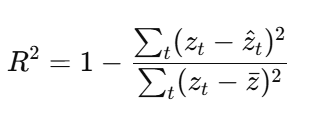

- Visual comparison of trajectories

% Marchenko–Pastur threshold
s_eeg_like_T = s_eeg_like';
eig_vals = eig(cov(s_eeg_like_T));
[N, T] = size(s_eeg_like);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 5 PCs



% [s_i_test, param_test, h_f_test] = sampleMorrellModel(param);
% [s_eeg_like_test, h_f_processed_test] = spike_to_eeg(s_i_test,h_f_test, param, target_bin_size,tau, group_size, smooth_sigma);

### **The two linear methods: PCA, ICA**

- For the reconstruction error: divide by var per latent variable before calculating R^2

-  For orerall accuracies, also show the PC trace over the period

- also calcualte various time delays vs. R^2

% 1. PCA Analysis
% Run PCA on training data
[coeff, score, ~, ~, explained] = pca(s_eeg_like_T);

% TODO: also calcualte various time delays vs. R^2

h_f_recon = zeros(size(h_f_normalized));
reconstruction_error_pca = zeros(num_sig_components, param.N_F,2); % The 3rd dimension: 1 for R^2, 2 for MSE

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % Train
        w = lsqlin(score(:,1:idx), h_f_normalized(:,f));
        h_f_recon(:,f) = score(:,1:idx) * w;
        % reconstruction_error_pca(idx, f) = mean((h_f(:,f) - h_f_recon_train).^2);
        numerator = sum((h_f_normalized(:,f) - h_f_recon(:,f)).^2);
        denominator = sum((h_f_normalized(:,f) - mean(h_f_normalized(:,f))).^2);
        reconstruction_error_pca(idx, f,1) = 1 - (numerator / denominator);
        reconstruction_error_pca(idx, f,2) = mean((h_f_normalized(:,f) - h_f_recon(:,f)).^2);
    end
    
end

s_eeg_reconstructed = score * coeff';

% Calculate the Welch PSD for the normalized latent and its
% reconstruction
[H_F_welch_psd_norm, f_welch_psd_norm] = pwelch(h_f_normalized, window,overlap,nfft,fs);

[H_F_welch_psd_recon, f_welch_psd_recon] = pwelch(h_f_recon, window,overlap,nfft,fs);

figure('Position',[50 50 1000 800])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);
sgtitle('Latent variables Z(t) and $\hat{z}(t)$', 'Interpreter', 'latex')

for f=1:param.N_F
    nexttile;
    hold on;
    plot(h_f_normalized(:, f),'LineStyle', '-', 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
    plot(h_f_recon(:, f), 'LineStyle', '--','LineWidth',1,'Color', 'k','DisplayName', ['$\hat{Z}$ (t) ' num2str(f)]);
    xlabel('Time bins')
    ylabel('Latent field amplitude')
    % xlim([0 1000]);
    legend('Show','Interpreter', 'latex');
    hold off;
end

figure('Position',[50 50 1000 950])
tiledlayout(num_sig_components, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
pc_colors = lines(num_sig_components);
sgtitle('PC Traces');

for pc=1:num_sig_components
    nexttile;
    plot(score(:,pc), 'LineStyle', '-', 'Color', pc_colors(pc,:),'DisplayName', ['PC(t) ' num2str(pc)]);
    xlabel('Time bins')
    ylabel('PC amplitude')
    
    legend('show');
end

figure('Position',[50 50 1200 300])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile
for f=1:param.N_F
    loglog(f_welch_psd_norm, H_F_welch_psd_norm(:,f),'Color',h_f_colors(f,:),'DisplayName',['Welch(Z_{' num2str(f) '} (t))']); % 
    hold on;
end
xticks([1, 4, 8, 10, 13, 20, 30, 50]) 
xlabel('Frequency bins')
ylabel('Power/Freq (dB/Hz)')
title('Welch Periodogram for normalized Z(t)','Interpreter', 'latex')
legend('show');
xlim([1, fs/2]);
ylim([1e-7 1]);
hold off;

nexttile
for f=1:param.N_F
    loglog(f_welch_psd_recon, H_F_welch_psd_recon(:,f),'Color',h_f_colors(f,:),'DisplayName',['Welch($\hat{Z}_{' num2str(f) '}$ (t))']); % 
    hold on;
end
xticks([1, 4, 8, 10, 13, 20, 30, 50]) 
xlabel('Frequency bins')
ylabel('Power/Freq (dB/Hz)')
title('Welch Periodogram for $\hat{Z}$ (t)','Interpreter', 'latex')
legend('show','Interpreter', 'latex');
xlim([1, fs/2]);
ylim([1e-7 1]);
hold off;

- **Visual Comparison of the Z(t) with **$\hat{Z} \left(t\right)$: The reconstruction of latent 4 is having a higgh variation, comapred to other 3 latents.

figure('Position',[50 50 800 600])
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile
plot(cumsum(explained), 'o-');
xlabel('Number of PCs');
ylabel('Cumulative Variance Explained (%)');
title('PCA Explained Variance');

nexttile
for f = 1:param.N_F
    hold on;
    plot(reconstruction_error_pca(:,f,1), 'LineStyle', '-','Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['R^2 ' num2str(f)]);
    plot(reconstruction_error_pca(:,f,2), 'LineStyle', '--','Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['MSE ' num2str(f)]);
end
% Adding axis labels and title
xlabel('Feature Index'); % X-axis label
ylabel('R² Value');      % Y-axis label
title('PCA R² Values for Different Features'); % Title
grid('on');
hold off;
legend('show');

- Increase in R^2 for latent 4, 3, and 2 close to 1, shows improved reconstruction. For Latent 1 the improvement is much smaller starting from PC 4 to 5 and 6, and latent 4 has the best reconstruction, since it gets to 0.9 by PC 3 closest to 1.

#### The effect of time delays on Reconstruction Error, R^2

- The higher the time delays, tau, the lower the reconstruction error. For example for latent 4 with tau of 10 it has R^2 of 0.9 and MSE of 0.1. 

% Run ICA with PCA whitening to num_comps
EEG = pop_runica(EEG, 'extended',1, 'pca', num_sig_components, 'interrupt','off');


         is not modeling the entire data, only the PCA-reduced data.
Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [5,50000] = 5 channels, 50000 frames/nAfter PCA dimension reduction,
  finding 5 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 2000 frames per ICA weight ((25)^2 = 50000 weights, Initial learning rate will be 0.001, block size 55.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -2.89812 to 5.08705
Reducing the data to 5 principal dimensions...
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Begin

icasig = double(EEG.icaact)';  % time × ICs

% Reconstruction error per latent on train & test
reconstruction_error_ica = zeros(num_sig_components, param.N_F,2); % The 3rd dimension: 1 for R^2, 2 for MSE
h_f_reconstructed_ica = zeros(size(h_f_processed));

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % fit on train
       % Reconstruct latent field f from first 'idx' ICs using least-squares
        x = lsqlin(icasig(:,1:idx), h_f_normalized(:,f));
        h_f_reconstructed_ica(:,f) = icasig(:,1:idx) * x;
        % rec_err(idx,f) = mean((h_f(:,f) - h_f_reconstructed_ica).^2);
        numerator = sum((h_f_normalized(:,f) - h_f_reconstructed_ica(:,f)).^2);
        denominator = sum((h_f_normalized(:,f) - mean(h_f_normalized(:,f))).^2);
        reconstruction_error_ica(idx, f,1) = 1 - (numerator / denominator);
        reconstruction_error_ica(idx, f,2) = mean((h_f_normalized(:,f) - h_f_reconstructed_ica(:,f)).^2);
    end
end

figure('Position',[50 50 1000 950])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);
sgtitle('ICA Latent variables Z(t) and $\hat{z}(t)$', 'Interpreter', 'latex')

for f=1:param.N_F
    nexttile
    hold on;
    plot(h_f_normalized(:, f),'LineStyle', '-', 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
    plot(h_f_reconstructed_ica(:, f), 'LineStyle', '--','Color', 'k','DisplayName', ['$\hat{Z}$ (t) ' num2str(f)]);
    xlabel('Time bins');
    ylabel('Latent field amplitude');
    %xlim([0 1000]);
    legend('Show','Interpreter', 'latex');
    hold off;
end

- **Visual Comparison of the Z(t) with **$\hat{Z} \left(t\right)$: The reconstruction is missing the high frequency activity and the peak and throughs don't match perfectly.

figure('Position',[50 50 800 300])
tiledlayout(1, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile
for f = 1:param.N_F
    hold on;
    plot(reconstruction_error_ica(:,f,1),'Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['R^2 ' num2str(f)]);
    plot(reconstruction_error_pca(:,f,2), 'LineStyle', '--','Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['MSE ' num2str(f)]);
end
% Adding axis labels and title
xlabel('Feature Index'); % X-axis label
ylabel('R² Value');      % Y-axis label
title('ICA R² Values for Different Features'); % Title
grid on;
hold off;
legend('show');

- Similar results to  ICA: Increase in R^2 for latent 4, 3, and 2 close to 1, shows improved reconstruction. For Latent 4 gets to 0.7 by PC 3, while latent 1 it keeps improving with the biggest improvement from PC 5 to 6.

### Two Non-linear methods: UMAP and t-SNE

% UMAP
n_neighbors_values = [5, 10, 15, 30, 50, 100];
min_dist_values     = [0.1, 0.25, 0.5, 0.75];
n_comp = num_sig_components;

figure('Position',[100,100, 1200, 800]);
tiledlayout(length(n_neighbors_values), length(min_dist_values), 'TileSpacing', 'compact');
warning('off', 'MATLAB:HandleGraphics:ObsoletedProperty:JavaFrame');

cluster_idx = kmeans(h_f_normalized , 4);


plot_idx = 1;
for curr_n_neighbors = n_neighbors_values
    for curr_min_dist = min_dist_values
        [umap_s_i, umap_params] = run_umap(s_eeg_like_T, 'n_neighbors', curr_n_neighbors,...
            'min_dist', curr_min_dist,'n_components', n_comp, 'verbose', 'none', 'gui', false);

        nexttile(plot_idx)
        % scatter(umap_s_i(:,1), umap_s_i(:,2), 5, 'filled');
        gscatter(umap_s_i(:,1), umap_s_i(:,2), cluster_idx);
        title({['n=' num2str(curr_n_neighbors)], ['minDist=' num2str(curr_min_dist)]});
        axis tight; axis off;
        plot_idx = plot_idx + 1;
    end
end

ans =     'Error using UmapUtil.GetArgs (line 162)
     1 arg(s) unrecognized by run_umap
     Error in UmapUtil.Initialize (

Error using SuhRunUmap (line 68)
1 arg(s) unrecognized by run_umap
Error in run_umap (line 1328)
this=SuhRunUmap(nargo

n=50 with minDist 0.5 has the yellow latent class on the left end and some red to the right side. Slightly better than other combinations. 

n_neighbors = 50;
min_dist    = 0.5;

[umap_s_i, ~] = run_umap(s_eeg_like_T, 'n_neighbors', n_neighbors, 'min_dist', min_dist, ...
    'n_components', num_sig_components, 'verbose', 'none', 'gui', false);

cluster_idx = kmeans(h_f_normalized, param.N_F);  % cluster based on true latent dynamics

figure('Position', [100, 100, 800, 600]);
gscatter(umap_s_i(:,1), umap_s_i(:,2), cluster_idx);
xlabel('UMAP Dimension 1');
ylabel('UMAP Dimension 2');
title({['UMAP Colored by Latent Variable Z(t)'], ...
       ['n = ' num2str(n_neighbors)], ...
       ['minDist = ' num2str(min_dist)]});
colormap turbo;
colorbar; grid on;

reconstruction_error_umap = zeros(num_sig_components, param.N_F, 2);
h_f_reconstructed_umap = zeros(size(h_f_normalized));

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % Reconstruct latent field f from first 'idx' UDs using least-squares
        x_umap = lsqlin(umap_s_i(:, 1:idx), h_f_normalized(:,f));
        h_f_reconstructed_umap(:,f) = umap_s_i(:, 1:idx) * x_umap;
        % reconstruction_error_umap(idx,f) = mean((h_f_processed(:,f) - h_f_reconstructed_umap).^2);
        numerator = sum((h_f_normalized(:,f) - h_f_reconstructed_umap(:,f)).^2);
        denominator = sum((h_f_normalized(:,f) - mean(h_f_normalized(:,f))).^2);
        reconstruction_error_umap(idx, f, 1) = 1 - (numerator / denominator);
        reconstruction_error_umap(idx, f,2) = mean((h_f_normalized(:,f) - h_f_reconstructed_umap(:,f)).^2);
    end
end

figure('Position',[50 50 1000 800])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);
sgtitle('UMAP Latent variables Z(t) and $\hat{z}(t)$', 'Interpreter', 'latex')

for f=1:param.N_F
    nexttile
    hold on;
    plot(h_f_normalized(:, f),'LineStyle', '-', 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
    plot(h_f_reconstructed_umap(:, f), 'LineStyle', '--','Color', 'k','DisplayName', ['$\hat{Z}$ (t) ' num2str(f)]);
    xlabel('Time bins')
    ylabel('Latent field amplitude')
    % xlim([0 1000]);
    legend('Show','Interpreter', 'latex');
    hold off;
end

- The Z hat looks similar for UMAP, than PCA or ICA. It is lacking spatial resolution. The latent 4 looks best. 

figure('Position',[50 50 800 300])
tiledlayout(1, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile
for f = 1:param.N_F
    hold on;
    plot(reconstruction_error_umap(:,f,1),'Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['R^2 ' num2str(f)]);
    plot(reconstruction_error_umap(:,f,2), 'LineStyle', '--','Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['MSE ' num2str(f)]);    
end
% Adding axis labels and title
xlabel('Feature Index'); % X-axis label
ylabel('R² Value');      % Y-axis label
title('UMAP R² Values for Different Features'); % Title
grid on;
hold off;
legend('show');

- Latent 4 has the best R^2 after PC3 and gets to 0.85 by PC5. Large increase in R^2 for latent 3 from PC 3 to 5 ending in 0.8 R^2, and for Latent 1 that is equal to 0.1. Latent 2 has a small improvement from PC3 to 5. 

% t-SNE
% Systematic approach to selecting perplexity for temporal factors
% perplexity_values = [3, 4, 5, 6, 7];
perplexity_values = [5, 10, 15, 30, 40, 50];
% num_dims = 2;  % Using 2D for easier comparison
num_dims = num_sig_components;
% Preallocate cell arrays to store results
Y_results = cell(length(s_eeg_like_T), 1);

figure('Position',[100,100, 1000, 1000]);
tiledlayout(3, 2, 'TileSpacing', 'compact');
% warning('off', 'MATLAB:HandleGraphics:ObsoletedProperty:JavaFrame');

cluster_idx = kmeans(h_f_normalized , 4);

plot_idx = 1;
for curr_perplexity = perplexity_values

    Y_results = tsne(s_eeg_like_T, 'Perplexity', curr_perplexity, 'NumDimensions', num_dims, 'NumPCAComponents', num_sig_components);
    
    nexttile(plot_idx)
    % scatter(umap_s_i(:,1), umap_s_i(:,2), 5, 'filled');
    gscatter(Y_results(:,1), Y_results(:,2), cluster_idx);
    title(['Perplexity = ', num2str(curr_perplexity)]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    colorbar;
    axis tight;

    plot_idx = plot_idx + 1;
    
end
sgtitle('Testing Different t-SNE Perplexity values');

perplexity = 50;
num_dims = num_sig_components;
tsne_s_i = tsne(s_eeg_like_T, 'Perplexity', perplexity, 'NumDimensions', num_dims, ...
    'NumPCAComponents',   num_sig_components);

figure('Position',[100,100,600,600]);
gscatter(tsne_s_i(:,1), tsne_s_i(:,2), cluster_idx);
xlabel('t-SNE Dim 1');
ylabel('t-SNE Dim 2');
title(sprintf('t-SNE (Perp=%d, D=%d)', perplexity, num_dims));
colormap turbo; colorbar; grid on;

reconstruction_error_tsne = zeros(num_sig_components, param.N_F, 2);
h_f_reconstructed_tsne = zeros(size(h_f_processed));

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % Reconstruct latent field f from first 'idx' UDs using least-squares
        x_tsne = lsqlin(tsne_s_i(:, 1:idx), h_f_normalized(:,f));
        h_f_reconstructed_tsne(:,f) = tsne_s_i(:, 1:idx) * x_tsne;
        % reconstruction_error_umap(idx,f) = mean((h_f_processed(:,f) - h_f_reconstructed_umap).^2);
        numerator = sum((h_f_normalized(:,f) - h_f_reconstructed_tsne(:,f)).^2);
        denominator = sum((h_f_normalized(:,f) - mean(h_f_normalized(:,f))).^2);
        reconstruction_error_tsne(idx, f, 1) = 1 - (numerator / denominator);
        reconstruction_error_tsne(idx, f,2) = mean((h_f_normalized(:,f) - h_f_reconstructed_tsne(:,f)).^2);
    end
end

figure('Position',[50 50 1000 800])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);
sgtitle('t-SNE Latent variables Z(t) and $\hat{z}(t)$', 'Interpreter', 'latex')

for f=1:param.N_F
    nexttile
    hold on;
    plot(h_f_processed(:, f),'LineStyle', '-', 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
    plot(h_f_reconstructed_tsne(:, f), 'LineStyle', '--','Color', 'k','DisplayName', ['$\hat{Z}$ (t) ' num2str(f)]);
    xlabel('Time bins')
    ylabel('Latent field amplitude')
    % xlim([0 1000]);
    legend('Show','Interpreter', 'latex');
    hold off;
end

- The Z hat for t-SNE looks better than UMAP. But still has medium frequency components as in ICA and PCA. 

figure('Position',[50 50 800 300])
tiledlayout(1, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile
for f = 1:param.N_F
    hold on;
    plot(reconstruction_error_tsne(:,f, 1),'Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['R^2 ' num2str(f)]);
    plot(reconstruction_error_tsne(:,f,2), 'LineStyle', '--','Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['MSE ' num2str(f)]);  
end
% Adding axis labels and title
xlabel('Feature Index'); % X-axis label
ylabel('R² Value');      % Y-axis label
title('t-SNE R² Values for Different Features'); % Title
grid on; 
hold off;
legend('show');

Latent 4 has big change in R^2 after PC4 and gets to 0.5 by PC6. Small increase in R^2 for latent 2 and for Latent 1 from PC 3 to 4 a small in crease, and by PC 6 it settles at 0.1. Latent 3 has small improvments till PC 3, and bigger improvements from PC 4 to 6 and ends up at 0.45 R^2. The MSE have similar thrends in the opposite direction of decreasing with increasing PC numbers. 

## 3. Frequency‑Resolved Analysis

**Why? **

              The latent variables may have different frequency content than the EEG signal. We want to know the limits of reconstruction and signatures of failure. 

A. CPSD / Spectral R2(f)R^2(f)

- Compute Fourier transforms .

- PCA, ICA

- UMAP, t-SNE

- For each dimension:

- Plot  across frequencies (for each latent dimension). Recommended to divide long time series into shorter “trials” (~3 seconds each) and average over these. 

N = size(h_f_normalized, 1);
trial_dur = 3;                 % seconds per "trial"
L         = trial_dur * fs;    % samples per trial
nTrials   = floor(size(h_f_normalized,1)/L);

fs = 100;  % or whatever your sample rate is
f = (0:L-1)*(fs/L);    % frequency vector for each trial

% Compute R^2(f)
R2_trials = zeros(L, param.N_F, nTrials);
Ht = zeros(L, param.N_F, nTrials);
Hr = zeros(L, param.N_F, nTrials);
Z_true_trials   = zeros(L, nTrials, param.N_F);
Z_recon_trials  = zeros(L, nTrials, param.N_F);


for tr = 1:nTrials
    idx = (tr-1)*L + (1:L);        % sample indices for this trial
  
    % extract one trial
    Z_true_trials(:,tr,:)  = h_f_normalized(idx, :);      
    Z_recon_trials(:,tr,:) = h_f_recon(idx, :);
    
    % FFT each latent dim
    Ht(:,:,tr) = fft(Z_true_trials(:,tr,:));     % size [L×N_F]
    Hr(:,:,tr) = fft(Z_recon_trials(:,tr,:));
    
    % compute trial‐wise R^2(f) for each dimension
    for fidx = 1:param.N_F
        num = abs(Ht(:,fidx,tr) - Hr(:,fidx,tr)).^2;
        den = abs(Ht(:,fidx,tr)).^2 + eps;   % avoid zero‐divide
        R2_trials(:,fidx,tr) = 1 - num./den;
    end
end

% Now average across trials
R2_avg = mean(R2_trials, 3);   % [L×N_F]
Ht_avg = mean(Ht, 3);
Hr_avg = mean(Hr, 3);

nHz = L/2+1;
f_plot = f(1:nHz);

bands = struct( ...
    'delta', [1 4], ...
    'theta', [4 8], ...
    'alpha', [8 13], ...
    'beta',  [13 30], ...
    'gamma', [30 50] ...
);
band_names = fieldnames(bands);
nBands = numel(band_names);

band_avg_R2 = zeros(nBands, param.N_F);  % rows: bands, cols: latent fields

for b = 1:nBands
    band = band_names{b};
    f_range = bands.(band);  % [f_low f_high]
    
    % Get indices within this band
    idx = f >= f_range(1) & f <= f_range(2);
    
    for fidx = 1:param.N_F
        band_avg_R2(b, fidx) = mean(R2_avg(idx, fidx));
    end
end


figure('Position',[50 50 1000 900])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
sgtitle('PCA Frequency Analysis: Fourier Transform and R^2');
nexttile
for fidx=1:param.N_F
    idx = 1:L/2+1;
    loglog(f_plot(idx), abs(Ht_avg(idx,fidx)),'Color',h_f_colors(fidx,:),'DisplayName',['Welch(Z_{' num2str(fidx) '} (f))']); % 
    hold on;
end
xlabel('Frequency (Hz)')
ylabel('|Z(f)|')
title('FFT Amplitude of Original Z(f)')
xlim([0.5, fs/2]);
xticks([1, 4, 8, 10, 13, 20, 30, 50]); % Example major ticks
legend('show','Location','southwest');
grid on;
hold off;

nexttile
for fidx=1:param.N_F
    idx = 1:L/2+1;
    loglog(f_plot(idx), abs(Hr_avg(idx,fidx)), 'Color',h_f_colors(fidx,:),'DisplayName',['Welch($\hat{Z}_{' num2str(fidx) '}$ (f))']); % 
    hold on;
end
xlabel('Frequency (Hz)')
ylabel('|Ẑ(f)|')
title('FFT Amplitude of Reconstructed $\hat{Z}$ (f)', 'Interpreter', 'latex')
xlim([0.5, fs/2])
% Set major tick values
xticks([1, 4, 8, 10, 13, 20, 30, 50]) % Example major ticks
legend('show', 'Interpreter', 'latex','Location','southwest');
grid on;
hold off;

nexttile
for fidx = 1:param.N_F
    hold on;
    plot(f, real(R2_avg(:,fidx)), 'LineStyle', '-','Marker', 'o','Color',h_f_colors(fidx,:),'DisplayName', ['R^2 ' num2str(fidx)]);
   
end
% Adding axis labels and title
xlim([0.5, fs/2]);
ylim([-50 0]);
xlabel('Frequency (Hz)');
ylabel('R^2(f)');
title('Frequency-resolved R^2 between original and PCA-reconstructed latent variables');
legend('show');
grid on;

nexttile;
bar(band_avg_R2');
set(gca, 'XTickLabel', arrayfun(@(i) sprintf('Z_{%d}', i), 1:param.N_F, 'UniformOutput', false));
ylim([-20 0]);
legend(band_names, 'Location', 'southeast');
ylabel('Mean R^2 in Band');
xlabel('Latent Variable');
title('Band-wise Average R^2(f) per Latent Variable');
grid on;

- Looking at FFT amplitude of true and reconstructed Z we see that after 8 Hz there is a decrease in the latent's amplitude variance, such that except latent 4, other latent variables variance approches zero after 13 Hz. Therefore, for the mid- to high beta band range the reconstruction is not performing well. 

- Looking at R^2, they are all at zero, or few bellow zero, which means variance in reconstruction is not true per frequency. Reconstruction is failing especially for latent variables with tau of 0.5 and 1.

- Looking at band average R^2, we see that for latent variables 1,2 and 3 are small negative numbers, except beta for latent 2 highlighting the reconstruction is worse than mean. Although, latent variable 4 have larger negative reconstruction for delta and gamma bands. This could be due to the trial window being too short for our model. The 3 seconds trial could be too short for small tau values.  

#### **B. Multitaper Coherence**

- Estimate coherence using multitaper methods (include 95% confidence intervals). Use Chronux (http://chronux.org)

- Identify frequency bands where coherence drops below statistical significance.

- Compare these bands across different reconstruction methods.

% define Chronux parameters
Chronux_params.Fs       = fs;       % sampling rate
Chronux_params.tapers   = [3 5];    % time–bandwidth product TW=3, K=5 tapers
Chronux_params.pad      = 0;        % no zero‑padding
Chronux_params.trialave = 1;        % average across trials if you have them
Chronux_params.err = [2 0];   % turn off jackknifed error bars

% First run one coherence to get sizes
[~, ~, ~, ~,~, f_coh] = coherencyc(Z_true_trials(:,:,1), Z_recon_trials(:,:,1), Chronux_params);
nFreq = numel(f_coh);  % = 257

coh_all  = zeros(nFreq, param.N_F);
conf_all = zeros(nFreq, param.N_F);

% Loop over latent dimensions
for i = 1:param.N_F
    [coh_all(:,i), ~, ~, ~, ~, ~, conf_all(:,i),~,~] = coherencyc(Z_true_trials(:,:,i), Z_recon_trials(:,:,i), Chronux_params);
end


% Parameters
latent_indices = 1:4;  % Latents to plot
R2_thresh = 0.05;       % Threshold for poor reconstruction
nLatents = numel(latent_indices);

figure('Position', [100, 100, 1000, 250 * nLatents]);
tiledlayout(nLatents, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
sgtitle('PCA Frequency-resolved R^2 and Coherence for Latents Z_1 to Z_4');

for i = 1:nLatents
    latent_idx = latent_indices(i);
    
    % Extract data
    coh       = coh_all(:, latent_idx);
    conf_low  = squeeze(conf_all(:, latent_idx));
    R2_interp = interp1(f, real(R2_avg(:, latent_idx)), f_coh, 'linear', 'extrap');

    % Identify frequencies where R^2 is low and coherence is nonsignificant
    fail_idx = (R2_interp < R2_thresh) & (coh < conf_low);

    nexttile
    yyaxis left
    plot(f_coh, R2_interp, 'b-', 'LineWidth', 2);
    ylabel('R^2(f)');
    ylim([-3, 1]);

    yyaxis right
    plot(f_coh, coh, 'k-', 'LineWidth', 1.5); hold on;
    plot(f_coh, real(conf_low), 'r--');
    ylabel('Coherence');
    ylim([-3, 1]);

    xlabel('Frequency (Hz)');
    title(sprintf('Z_{%d}: R^2(f) and Coherence', latent_idx));
    grid on;

    % Highlight failure frequencies
    for k = 1:length(f_coh)
        if fail_idx(k)
            x = f_coh(k);
            yyaxis right
            line([x x], [0 1.05], 'Color', [0.8 0.3 0.3], 'LineStyle', '--', 'LineWidth', 0.5);
        end
    end

    % Determine if failure lines were plotted
    legend_entries = {'R^2(f)', 'Coherence', '95% CI (lower)'};
    
    if any(fail_idx)
        legend_entries{end+1} = 'Failure';
    end
    
    legend(legend_entries, 'Location', 'northeast');
    
    xlim([0.5, fs/2]);
    xticks([1, 4, 8, 10, 13, 20, 30, 50]);
end

- The Coherence results shows that for the 4 latents between 2 Hz the coherence decrease and then increases till 3 Hz and it stabilizes. Latent 4 has the highest coherence at ~ 0.4 , latent 3 at ~ 0.22, latent 2 at ~ 0.15, and latent 1 at ~ 0.2. The R^2 

band_failure_frac = zeros(nBands,1);
for b = 1:nBands
  idx = f_coh >= bands.(band_names{b})(1) & f_coh <= bands.(band_names{b})(2);
  band_failure_frac(b) = sum(fail_idx(idx)) / sum(idx);
end
T = table(band_names, band_failure_frac);
disp(T);

- All frequency bands reconstructino R^2 below zero, and there is no frequency where coherence is significant and the reconstruction good. 

- I tried decreasing R^2 threshold from 0.2 to 0.1, and 0.1 to 0.05, to bee more lineant. But the reconstruction still fails. 

## ICA Reconstruction R^2 test and Coherence analysis

N = size(h_f_normalized, 1);
trial_dur = 3;                 % seconds per "trial"
L         = trial_dur * fs;    % samples per trial
nTrials   = floor(size(h_f_normalized,1)/L);

fs = 100;  % or whatever your sample rate is
f = (0:L-1)*(fs/L);    % frequency vector for each trial

% Compute R^2(f)
R2_trials = zeros(L, param.N_F, nTrials);
Ht = zeros(L, param.N_F, nTrials);
Hr = zeros(L, param.N_F, nTrials);
Z_true_trials   = zeros(L, nTrials, param.N_F);
Z_recon_ica_trials  = zeros(L, nTrials, param.N_F);


for tr = 1:nTrials
    idx = (tr-1)*L + (1:L);        % sample indices for this trial
  
    % extract one trial
    Z_true_trials(:,tr,:)  = h_f_normalized(idx, :);      
    Z_recon_ica_trials(:,tr,:) = h_f_reconstructed_ica(idx, :);
    
    % FFT each latent dim
    Ht(:,:,tr) = fft(Z_true_trials(:,tr,:));     % size [L×N_F]
    Hr(:,:,tr) = fft(Z_recon_ica_trials(:,tr,:));
    
    % compute trial‐wise R^2(f) for each dimension
    for fidx = 1:param.N_F
        num = abs(Ht(:,fidx,tr) - Hr(:,fidx,tr)).^2;
        den = abs(Ht(:,fidx,tr)).^2 + eps;   % avoid zero‐divide
        R2_trials(:,fidx,tr) = 1 - num./den;
    end
end

% Now average across trials
R2_avg = mean(R2_trials, 3);   % [L×N_F]
Ht_avg = mean(Ht, 3);
Hr_avg = mean(Hr, 3);

nHz = L/2+1;
f_plot = f(1:nHz);

bands = struct( ...
    'delta', [1 4], ...
    'theta', [4 8], ...
    'alpha', [8 13], ...
    'beta',  [13 30], ...
    'gamma', [30 50] ...
);
band_names = fieldnames(bands);
nBands = numel(band_names);

band_avg_R2 = zeros(nBands, param.N_F);  % rows: bands, cols: latent fields

for b = 1:nBands
    band = band_names{b};
    f_range = bands.(band);  % [f_low f_high]
    
    % Get indices within this band
    idx = f >= f_range(1) & f <= f_range(2);
    
    for fidx = 1:param.N_F
        band_avg_R2(b, fidx) = mean(R2_avg(idx, fidx));
    end
end


figure('Position',[50 50 1000 900])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
sgtitle('ICA Frequency Analysis: Fourier Transform and R^2');

nexttile
for fidx=1:param.N_F
    idx = 1:L/2+1;
    loglog(f_plot(idx), abs(Ht_avg(idx,fidx)),'Color',h_f_colors(fidx,:),'DisplayName',['Welch(Z_{' num2str(fidx) '} (f))']); % 
    hold on;
end
xlabel('Frequency (Hz)')
ylabel('|Z(f)|')
title('FFT Amplitude of Original Z(f)')
xlim([0.5, fs/2]);
xticks([1, 4, 8, 10, 13, 20, 30, 50]); % Example major ticks
legend('show','Location','southwest');
grid on;
hold off;

nexttile
for fidx=1:param.N_F
    idx = 1:L/2+1;
    loglog(f_plot(idx), abs(Hr_avg(idx,fidx)), 'Color',h_f_colors(fidx,:),'DisplayName',['Welch($\hat{Z}_{' num2str(fidx) '}$ (f))']); % 
    hold on;
end
xlabel('Frequency (Hz)')
ylabel('|Ẑ(f)|')
title('FFT Amplitude of Reconstructed $\hat{Z}$ (f)', 'Interpreter', 'latex')
xlim([0.5, fs/2])
% Set major tick values
xticks([1, 4, 8, 10, 13, 20, 30, 50]) % Example major ticks
legend('show', 'Interpreter', 'latex','Location','southwest');
grid on;
hold off;

nexttile
for fidx = 1:param.N_F
    hold on;
    plot(f, real(R2_avg(:,fidx)), 'LineStyle', '-','Marker', 'o','Color',h_f_colors(fidx,:),'DisplayName', ['R^2 ' num2str(fidx)]);
   
end
% Adding axis labels and title
xlim([0.5, fs/2]);
ylim([-50 0]);
xlabel('Frequency (Hz)');
ylabel('R^2(f)');
title('Frequency-resolved R^2 between original and ICA-reconstructed latent variables');
legend('show');
grid on;

nexttile;
bar(band_avg_R2');
set(gca, 'XTickLabel', arrayfun(@(i) sprintf('Z_{%d}', i), 1:param.N_F, 'UniformOutput', false));
ylim([-20 0]);
legend(band_names, 'Location', 'southeast');
ylabel('Mean R^2 in Band');
xlabel('Latent Variable');
title('Band-wise Average R^2(f) per Latent Variable');
grid on;

- Similar to PCA results: Looking at R^2, they are all at zero, or few bellow zero, which means variance in reconstruction is not true per frequency. Reconstruction is failing especially for latent variables with tau of 0.5 and 1.

% define Chronux parameters
Chronux_params.Fs       = fs;       % sampling rate
Chronux_params.tapers   = [3 5];    % time–bandwidth product TW=3, K=5 tapers
Chronux_params.pad      = 0;        % no zero‑padding
Chronux_params.trialave = 1;        % average across trials if you have them
Chronux_params.err = [2 0];   % turn off jackknifed error bars

% First run one coherence to get sizes
[~, ~, ~, ~,~, f_coh] = coherencyc(Z_true_trials(:,:,1), Z_recon_ica_trials(:,:,1), Chronux_params);
nFreq = numel(f_coh);  % = 257

coh_ica_all  = zeros(nFreq, param.N_F);
conf_ica_all = zeros(nFreq, param.N_F);

% Loop over latent dimensions
for i = 1:param.N_F
    [coh_ica_all(:,i), ~, ~, ~, ~, ~, conf_ica_all(:,i),~,~] = coherencyc(Z_true_trials(:,:,i), Z_recon_ica_trials(:,:,i), Chronux_params);
end


% Parameters
latent_indices = 1:4;  % Latents to plot
R2_thresh = 0.05;       % Threshold for poor reconstruction
nLatents = numel(latent_indices);

figure('Position', [100, 100, 1500, 250 * nLatents]);
tiledlayout(nLatents, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:nLatents
    latent_idx = latent_indices(i);
    
    % Extract data
    coh       = coh_ica_all(:, latent_idx);
    conf_low  = squeeze(conf_ica_all(:, latent_idx));
    R2_interp = interp1(f, real(R2_avg(:, latent_idx)), f_coh, 'linear', 'extrap');

    % Identify frequencies where R^2 is low and coherence is nonsignificant
    fail_ica_idx = (R2_interp < R2_thresh) & (coh < conf_low);

    nexttile
    yyaxis left
    plot(f_coh, R2_interp, 'b-', 'LineWidth', 2);
    ylabel('R^2(f)');
    ylim([-3, 1]);

    yyaxis right
    plot(f_coh, coh, 'k-', 'LineWidth', 1.5); hold on;
    plot(f_coh, real(conf_low), 'r--');
    ylabel('Coherence');
    ylim([-3, 1]);

    xlabel('Frequency (Hz)');
    title(sprintf('Z_{%d}: R^2(f) and Coherence', latent_idx));
    grid on;

    % Highlight failure frequencies
    for k = 1:length(f_coh)
        if fail_ica_idx(k)
            x = f_coh(k);
            yyaxis right
            line([x x], [0 1.05], 'Color', [0.8 0.3 0.3], 'LineStyle', '--', 'LineWidth', 0.5);
        end
    end

    % Determine if failure lines were plotted
    legend_entries = {'R^2(f)', 'Coherence', '95% CI (lower)'};
    
    if any(fail_idx)
        legend_entries{end+1} = 'Failure';
    end
    
    legend(legend_entries, 'Location', 'northeast');
    
    xlim([0.5, fs/2]);
    xticks([1, 4, 8, 10, 13, 20, 30, 50]);
end
sgtitle('Frequency-resolved R^2 and Coherence for Latents Z_1–Z_4');

band_failure_frac = zeros(nBands,1);
for b = 1:nBands
  idx = f_coh >= bands.(band_names{b})(1) & f_coh <= bands.(band_names{b})(2);
  band_failure_frac(b) = sum(fail_ica_idx(idx)) / sum(idx);
end
T = table(band_names, band_failure_frac);
disp(T);

- Similar to PCA results:  All frequency bands reconstructino R^2 below zero, and there is no frequency where coherence is significant and the reconstruction good. 

## 4. Perturbation Robustness

Think about constructing a **"failure map"**:

- Use synthetic variations of the latent variables (e.g., higher frequencies (smaller autocorrelation,  ), more nonlinear coupling of latent variables to the spiking activity  (different ), less spatial footprint (sparser  ).

- For each, record how well different methods can recover them.

- Summarize which properties (time scale, frequency, spatial spread) affect recoverability and method performance.

#### Perturbation Grid: various time scales (tau_f), coupling strengths/nonlinearity (eta_val, eps_val), and spatial spread (J_if, sparcity or scale)

taus    = [0.1, 0.5, 1, 3, 10, 30];
etas    = [1, 3, 10];
spars   = [0.1, 0.3, 0.5, 0.8];
Ntau    = numel(taus);
Neta    = numel(etas);
Nspars  = numel(spars);

results = struct(); 


#### Run Simulation and compute recovery metrics

param.N_neur = 256; % Number of "neurons" (binary units)
param.N_F = 1; % Number of latent fields hₘ(t)
param.T = 1000; % Total simulation time (in seconds), min duration at 1000 sec

% Initialize performance metrics for PCA and ICA
fs = 100;  % or whatever your sample rate is

trial_dur = 3;                 % seconds per "trial"
L = trial_dur * fs;    % samples per trial
f = (0:L-1)*(fs/L);    % frequency vector for each trial

R2_pca = zeros(param.N_F, 1);
R2_ica = zeros(param.N_F, 1);

Nbands = 5; % delta, theta, alpha, beta, gamma

% Preallocate R² (one value per latent factor)
R2_all = zeros(Ntau, Neta, Nspars, param.N_F);
R2_thresh_perturb = 0.2;

% Preallocate band failure fractions (e.g., coherence < threshold)
band_failure_frac = zeros(Ntau, Neta, Nspars, param.N_F, Nbands);

% Optional: full coherence spectrum (e.g., 257 frequencies)
nFreq = 257;
coh_spectra = zeros(Ntau, Neta, Nspars, param.N_F, nFreq);

% Optional: failure flags (true/false) if overall recovery failed
recovery_failed = false(Ntau, Neta, Nspars, param.N_F);



for i=1:Ntau
    for j=1:Neta
        for k=1:Nspars
            param.tau_F      = taus(i);
            param.eta_val    = etas(j);
            param.eps_val    = etas(j)*1;   % for example
            param.fixJ_if    = sprandn(param.N_neur, param.N_F, spars(k));
            
            % simulation
            [s_i, param, h_f] = sampleMorrellModel(param);
            
            target_bin_size = 0.02; % 50 ms
            tau = 15; % Post-synaptic kernel, Alpha kernel's number of bins to the peak of the kernel
            smooth_sigma = 2; % Std. Dev. of the Gaussian kernel in bins
            group_size = 8; % grouping of neurons per channel
            
            [s_eeg_like, h_f_processed] = spike_to_eeg(s_i, h_f, param, target_bin_size, tau, group_size, smooth_sigma);
            % Normalize latent variables by their variance (per column)
            h_f_normalized = h_f_processed ./ std(h_f_processed, 0, 1);  % Time × N_F
            Z_true = h_f_normalized;

            % ====== Recovery Pipeline (e.g., PCA or ICA) ======
            % Marchenko–Pastur threshold
            s_eeg_like_T = s_eeg_like';
            eig_vals = eig(cov(s_eeg_like_T));
            [N, T] = size(s_eeg_like);
            Q = T / N;
            sigma2 = mean(eig_vals);           % crude estimate of noise variance
            lambda_max = sigma2 * (1 + sqrt(1/Q))^2;
            
            % Find number of components above the MP threshold
            num_sig_components = sum(eig_vals > lambda_max);
            fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

            % Perform recovery analysis using PCA
            [~, score, ~, ~, ~] = pca(s_eeg_like_T);
            Z_recon = zeros(size(h_f_normalized));
            
            for idx = 1:num_sig_components
                for f = 1:param.N_F
                    % Train
                    w = lsqlin(score(:,1:idx), Z_true(:,f));
                    Z_recon(:,f) = score(:,1:idx) * w;                    
                end
            end

            
            % Run R² or coherence metric, e.g.:
            
            [Z_true_trials, Z_recon_trials] = make_trial_matrices(Z_true, Z_recon, L);
            [coh, f_coh, confC] = compute_coherence(Z_true_trials, Z_recon_trials, fs);
            R2_vals = compute_R2(Z_true, Z_recon);
            frac_fail = compute_band_failure_fraction(coh, f_coh, R2_thresh_perturb);

            % ====== Store Outputs ======
            for f = 1:param.N_F
                R2_all(i,j,k,f) = R2_vals(f);
                band_failure_frac(i,j,k,f,:) = frac_fail(f,:);
                coh_spectra(i,j,k,f,:) = coh(:,f);

                recovery_failed(i,j,k,f) = R2_vals(f) < R2_thresh_perturb;
            end

        end
    end
end

Marchenko–Pastur suggests keeping 5 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 3 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 8 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 7 PCs
Marchenko–Pastur suggests keeping 3 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 6 PCs
Marchenko–Pastur suggests keeping 3 PCs
Marchenko–Pastur suggests keeping 3 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 8 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 8 PCs
Marchenko–Pastur suggests keeping 4 PCs
Marchenko–Pastur suggests keeping 3 PCs
Marchenko–Pastur suggests keeping 2 PCs
Marchenko–Pastur suggests keeping 5 PCs


fprintf('Recovery failed for the following parameter combinations:\n');

Recovery failed for the following parameter combinations:


fail_idx = find(recovery_failed);
[row, col, pg] = ind2sub(size(recovery_failed), fail_idx);

failed_table = table(taus(row)', etas(col)', spars(pg)', ...
    'VariableNames', {'tau', 'eta', 'sparsity'});

disp(failed_table);

    tau    eta    sparsity
    ___    ___    ________
    0.1     1       0.1   
    0.1     3       0.1   
    0.1    10       0.1   
    0.1     1       0.3   
    0.1     3       0.3   
    0.1    10       0.3   
    0.1     1       0.5   
    0.1     3       0.5   
    0.1    10       0.5   
    0.1     1       0.8   
    0.1     3       0.8   
    0.1    10       0.8   


- No matter the eta or sparsity values, the tau =  0.1 reconstruction R^2 for PCA failed. 

mean_R2_per_setting = mean(R2_all, 4);  % Average across latent dims
mean_fail_rate = mean(band_failure_frac(:));  % Overall failure rate

#### Visualizing the failiur Map

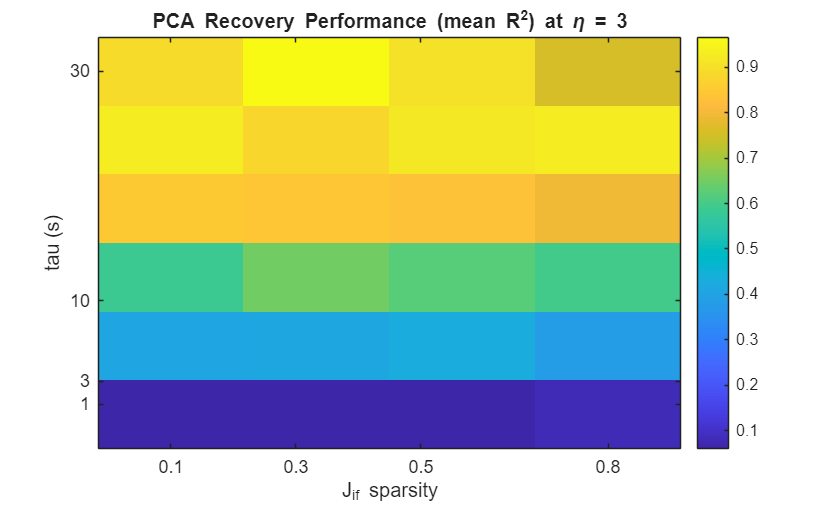

%% === Heatmap of Mean R² across τ and Sparsity at Fixed η ===
fixedEta = 3;
j = find(etas == fixedEta);  % fixed eta index
perfMat = zeros(Ntau, Nspars);

for i = 1:Ntau
    for k = 1:Nspars
        perfMat(i,k) = mean(R2_all(i,j,k,:));  % mean over latent dims
    end
end

figure;
imagesc(spars, taus, perfMat);
yticks([1, 3, 10, 30]);
xticks ([0.1, 0.3, 0.5, 0.8]);
set(gca,'YDir','normal');
colorbar;
xlabel('J_{if} sparsity');
ylabel('tau (s)');
title(sprintf('PCA Recovery Performance (mean R^2) at \\eta = %g', fixedEta));

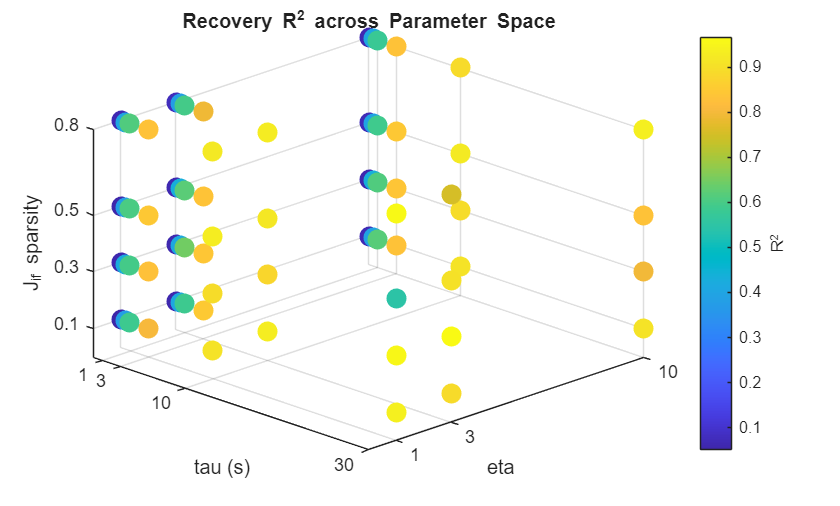


% Get grid of parameter combinations
[TAU, ETA, SPARS] = ndgrid(taus, etas, spars);

% Get average R² across latent dims
R2_avg = squeeze(mean(R2_all, 4));  % shape: [length(taus) x length(etas) x length(spars)]

% Flatten to vectors for scatter3
x = TAU(:);
y = ETA(:);
z = SPARS(:);
c = R2_avg(:);  % color (R² value)

% Plot
figure;
scatter3(x, y, z, 100, c, 'filled');
xticks([1, 3, 10, 30]);
zticks ([0.1, 0.3, 0.5, 0.8]);
yticks([1, 3, 10]);
xlabel('tau (s)');
ylabel('eta');
zlabel('J_{if} sparsity');
title('Recovery R^2 across Parameter Space');
cb = colorbar;
cb.Label.String = 'R^2';
view(45, 30);
grid on;

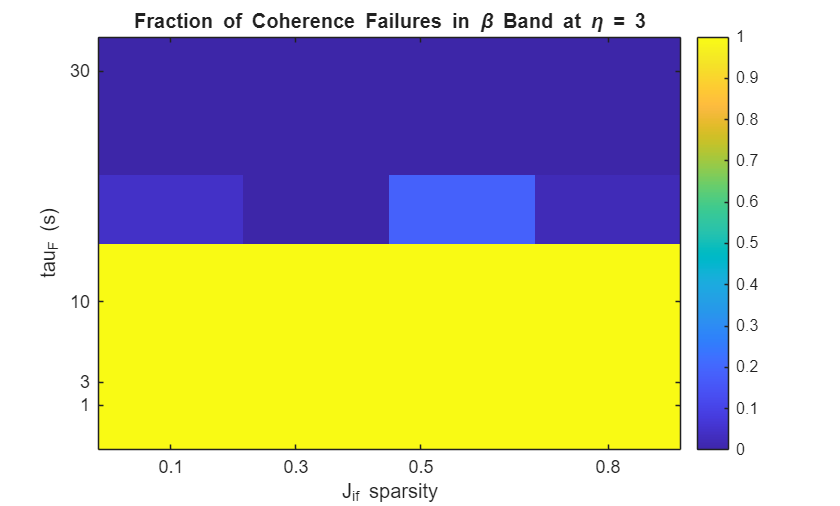


%% === Coherence Failure Fraction Visualization ===
% Optional: visualize failure rate in specific frequency band (e.g., beta)
band_labels = {'\delta', '\theta', '\alpha', '\beta', '\gamma'};
target_band = 4;  % beta

fail_frac_mat = zeros(Ntau, Nspars);
for i = 1:Ntau
    for k = 1:Nspars
        fail_frac_mat(i,k) = mean(band_failure_frac(i,j,k,:,target_band));
    end
end

figure;
imagesc(spars, taus, fail_frac_mat);
set(gca,'YDir','normal');
colorbar;
xticks ([0.1, 0.3, 0.5, 0.8]);
yticks([1, 3, 10, 30]);
xlabel('J_{if} sparsity');
ylabel('tau_F (s)');
title(sprintf('Fraction of Coherence Failures in %s Band at \\eta = %g', band_labels{target_band}, fixedEta));


%% === Optional: Global Failure Rate Summary ===
fprintf('Total mean failure rate across all perturbations and bands: %.2f%%\n', ...
    100 * mean_fail_rate);

Total mean failure rate across all perturbations and bands: 39.55%
